## Simulate Dynamics in Matlab

### Solve an ODE with ode45

`ode45` numerically solves an ODE in the following form:

    `[y, t] = ode45(odefun, tspan, y0)`

**[y, t]** are the tesulting y and time values from the ODE

**odefun** is the function that returns derivative values at the given time points

    `odefun` should be in the form: `function dydt = odefun(t,y)`

  If multiple arguements are required for the function:

        `odefun(t, y, a, b, c)`

        `[t,y] = ode45(@(t,y) odefun(t,y,a,b,c), tspan, ic)`

**tspan** is the time points for the function to be evluated at

**y0** is the initial value of the function at the first time point

#### Example:


$$\frac{dy(t)}{dt} =  -y(t) + 1$$
 

From 0 to 10 seconds 


$$y(0) = 0$$


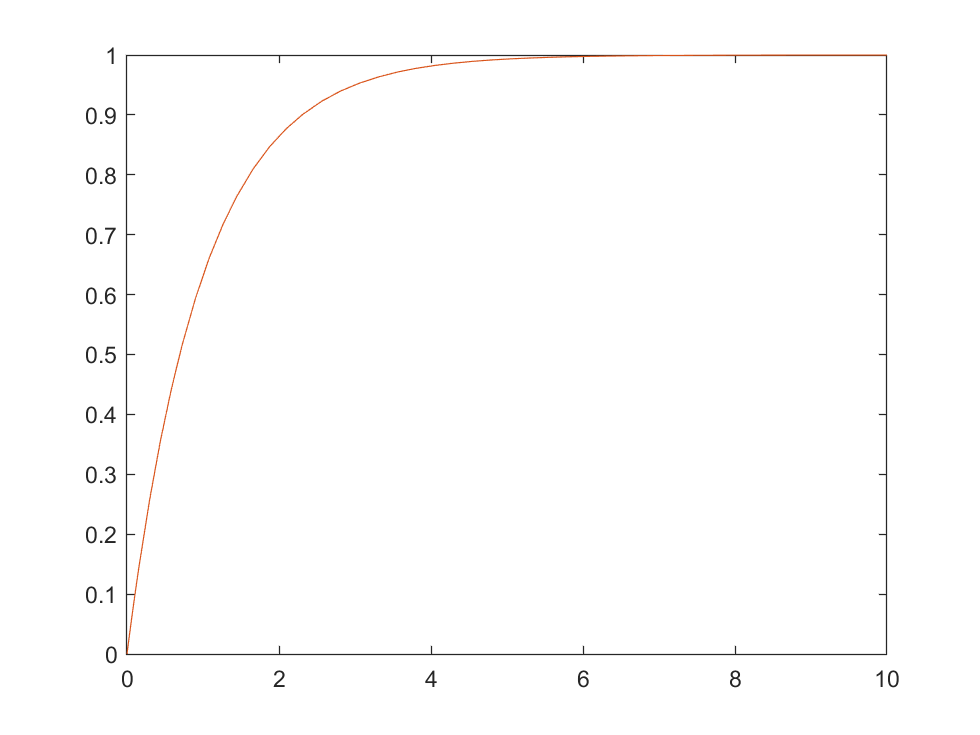

clc;clear all; close all;
% Note that funcitons must appear at the bottom 
time = [0 10]; % Time points
y0 = [time(1) 0]; % initial value

[tm, y] = ode45(@(t,y) ode_ex1(t, y), time, y0);
plot(tm, y)

#### Exercise1:


$$5\frac{dy}{dt}=-y(t) + u(t)
y(0) = 1; u(t) = 2s(t-10)
$$


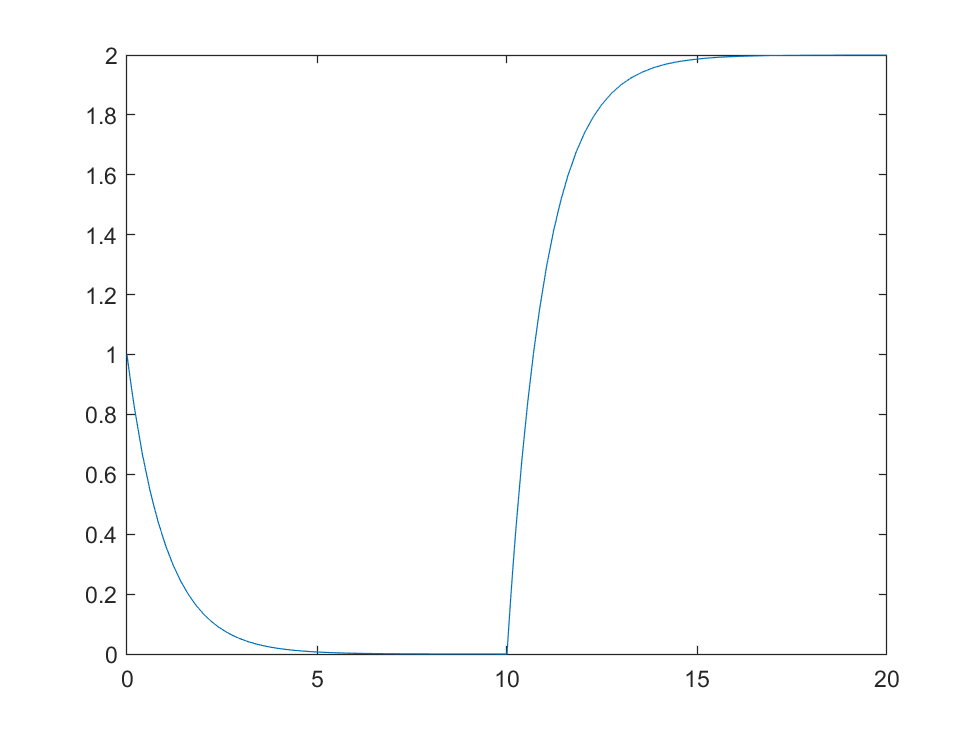

[tm, y] = ode45(@(t,y) ode_ex2(t, y), [0,20], 1);
plot(tm, y)

#### Exercise 3:


$$\frac{dx(t)}{dt} = 3e^{-t}; \frac{dy(t)}{dt}= 3-y(t); x(0) = y(0) = 0$$


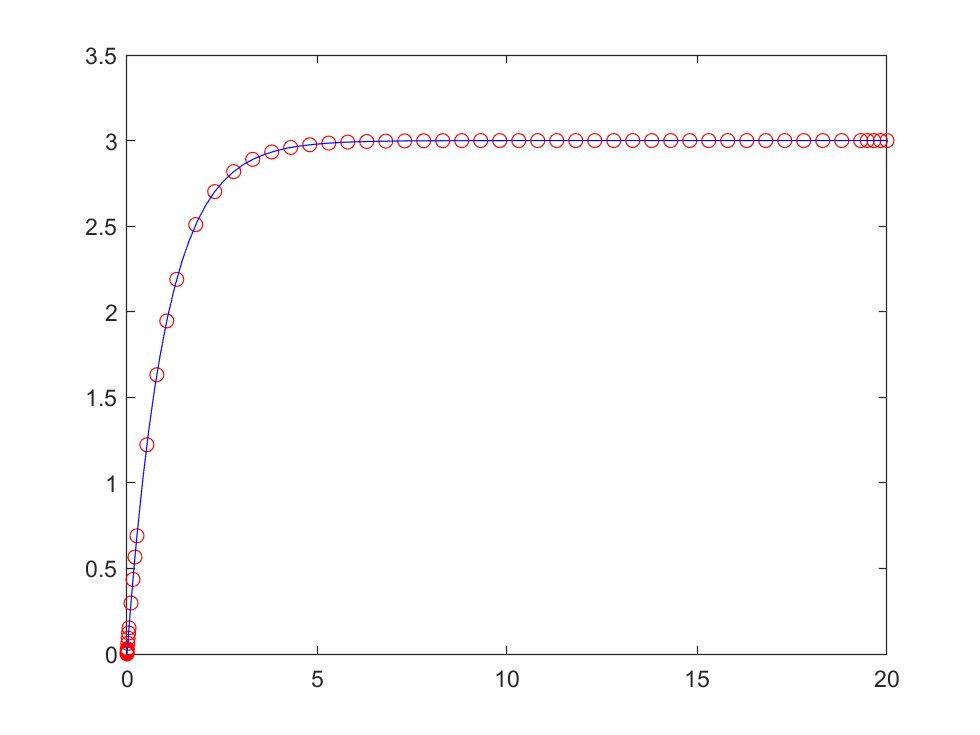

[tx, x] = ode45(@(t,x) ode_ex3a(t, x), [0,20], 0);
[ty, y] = ode45(@(t,y) ode_ex3b(t, y), [0,20], 0);
plot(tx, x, 'ro')
hold on;
plot(ty, y, 'b-')
hold off;

#### Exercise 4:


$$2\frac{dx(t)}{dt} = -x(t)+u(t)$$



$$5\frac{dy(t)}{dt}=-y(t) + x(t)$$



$$u=2s(t-5);x(0)=0;y(0)=0$$


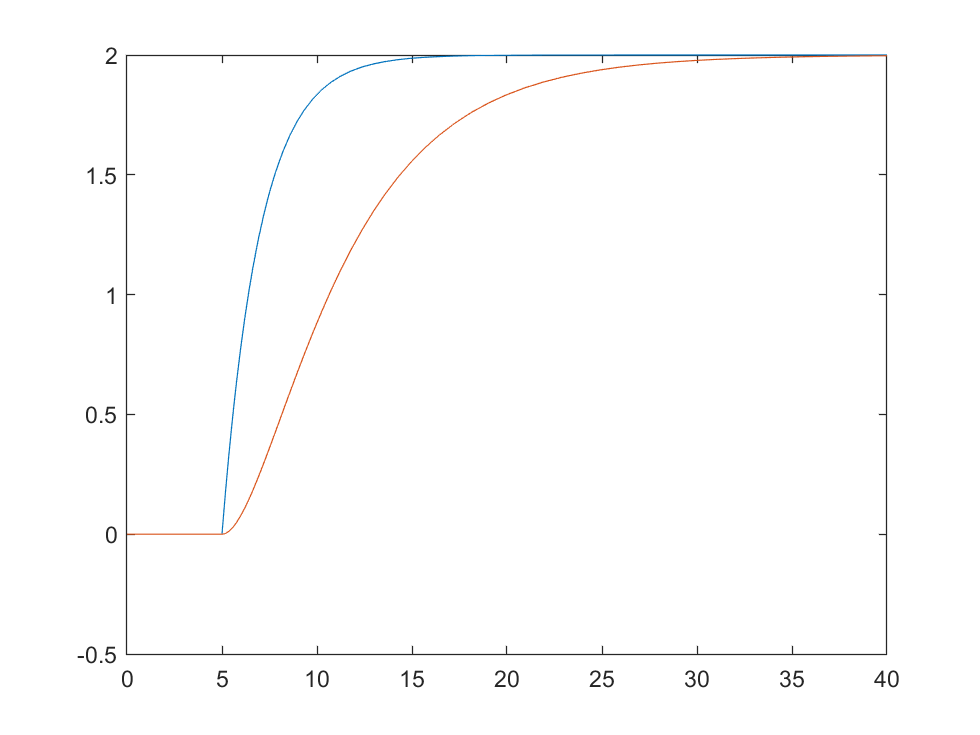

[tm, z] = ode45(@(t,z) ode_ex4(t, z), [0, 40], [0 0]);
x = z(:,1);
y = z(:,2);
plot(tm, x,)
hold on;
plot(tm, y)
hold off;

function dydt = ode_ex1(t,y)
    dydt = -y + 1;
end

function dydt = ode_ex2(t,y)
    if t >= 10
        u = 2;
    else
        u = 0;
    end
    dydt = -y + u;
end

function dxdt = ode_ex3a(t,y)
    dxdt = 3 * exp(-t);
end

function dydt = ode_ex3b(t,y)
    dydt = 3-y;
end

function dzdt = ode_ex4(t, z)
x = z(1);
y = z(2);

if t >= 5
    u = 2;
else
    u=0;
end

dxdt = (-x+u)/2;
dydt = (-y+x)/5;
dzdt = [dxdt; dydt;];
end